%% Konstanten
mu = 398600.4418;  % km^3/s^2, Erd-Gravitationsparameter

%% Beobachtungen aus Tabelle 1 (Aufgabe 1)
r1 = [3419.8556; 6019.8260; 2784.6002];   % km
r3 = [2434.9520; 6597.3867; 2521.5231];   % km

t1 = 0.0;                     % s
t3 = 2*60 + 33.04;            % 2 min 33.04 s
dt13 = t3 - t1;               % Flugzeit zwischen r1 und r3

%% 1a) Gauss-Lambert: v1 und v3 berechnen
[v1, v3] = functionsOrbit.lambertGauss(r1, r3, dt13, mu);

%% 1b) Kepler-Elemente aus (r1,v1) und (r3,v3)
[a1, e1, i1, RAAN1, omega1, nu1] = functionsOrbit.rv2coe(r1, v1, mu);
[a3, e3, i3, RAAN3, omega3, nu3] = functionsOrbit.rv2coe(r3, v3, mu);

% Du kannst dir die Werte einfach anzeigen lassen:
a1, e1, i1, RAAN1, omega1, nu1

a1 = 8.2913e+03

e1 = 0.1000

i1 = 0.4363

RAAN1 = 5.2360

omega1 = 2.0595

nu1 = 2.3473e-05

a3, e3, i3, RAAN3, omega3, nu3

a3 = 8.2913e+03

e3 = 0.1000

i3 = 0.4363

RAAN3 = 5.2360

omega3 = 2.0595

nu3 = 0.1571

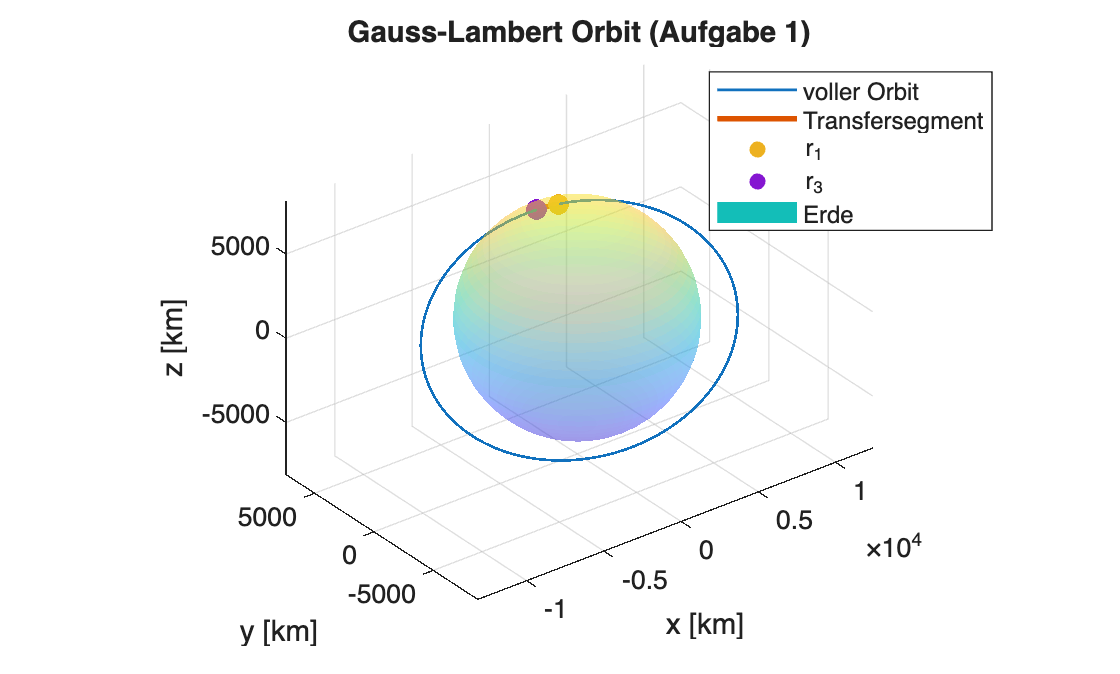


%% 1c) Orbit propagieren (Runge-Kutta) und plotten
T = 2*pi * sqrt(a1^3 / mu);   % Umlaufzeit [s]

dtStep = T / 500;             % Zeitschritt für die Integration
[tOrb, rOrb, vOrb] = functionsOrbit.propagateRK4(r1, v1, mu, T, dtStep);

% Transfersegment zwischen r1 und r3
[tSeg, rSeg, vSeg] = functionsOrbit.propagateRK4(r1, v1, mu, dt13, dtStep);

%% Plot: voller Orbit, Transfersegment, r1, r3 und Erde
figure; hold on; grid on; axis equal;

% Voller Orbit
plot3(rOrb(1,:), rOrb(2,:), rOrb(3,:), 'LineWidth', 1);

% Transfersegment
plot3(rSeg(1,:), rSeg(2,:), rSeg(3,:), 'LineWidth', 2);

% Punkte r1 und r3
scatter3(r1(1), r1(2), r1(3), 60, 'filled');
scatter3(r3(1), r3(2), r3(3), 60, 'filled');

% Erde als Kugel
[xe, ye, ze] = sphere(40);
Re = 6378.137;  % km
surf(Re*xe, Re*ye, Re*ze, 'FaceAlpha', 0.3, 'EdgeColor', 'none');

xlabel('x [km]');
ylabel('y [km]');
zlabel('z [km]');
legend('voller Orbit', 'Transfersegment', 'r_1', 'r_3', 'Erde');
title('Gauss-Lambert Orbit (Aufgabe 1)');
view(3);

TASK 2)

r1 = [0; 0; 6378.137];   % km
r2 = [0; -4464.696; -5102.509];   % km
r3 = [0; 5740.323; 3189.068];   % km

%% 2a) Gibbs-Methode: v2 berechnen
v2 = functionsOrbit.gibbs(r1, r2, r3, mu)

v2 =          0
    5.5311
   -5.1918


% Zum Vergleich mit dem Testwert aus dem Aufgabenblatt:
v2_test = [0; 5.531148; -5.191806];  % km/s
diff_v2  = v2 - v2_test

diff_v2 = 1.0e-06 *

         0
   -0.1315
    0.2217


norm_diff_v2 = norm(diff_v2)

norm_diff_v2 = 2.5782e-07

%% 2b) Kepler-Elemente aus r2 und v2
[a2, e2, i2, RAAN2, omega2, nu2] = functionsOrbit.rv2coe(r2, v2, mu);

a2, e2, i2, RAAN2, omega2, nu2

a2 = 6.6398e+03

e2 = 0.0408

i2 = 1.5708

RAAN2 = 1.5708

omega2 = 1.8442

nu2 = 2.1494

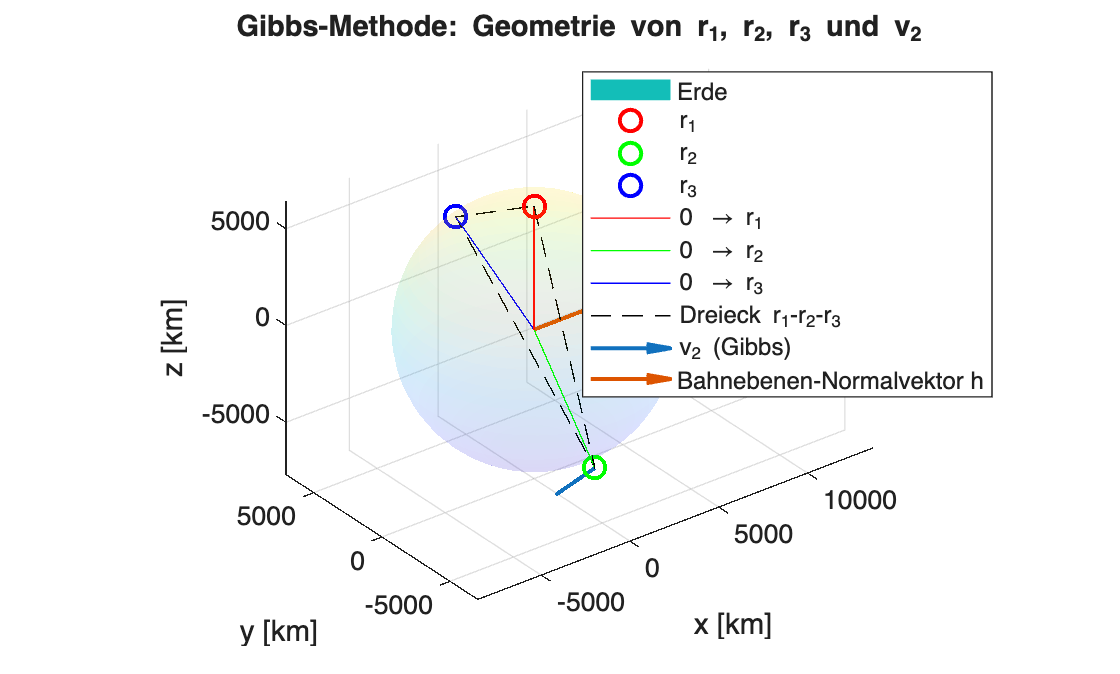

figure; hold on; grid on; axis equal;
title('Gibbs-Methode: Geometrie von r_1, r_2, r_3 und v_2');
xlabel('x [km]'); ylabel('y [km]'); zlabel('z [km]');

% Erde
[xe, ye, ze] = sphere(40);
Re = 6378.137;   % km
surf(Re*xe, Re*ye, Re*ze, 'FaceAlpha', 0.1, 'EdgeColor', 'none');

% Positionsvektoren r1, r2, r3
plot3(r1(1), r1(2), r1(3), 'ro', 'MarkerSize', 8, 'LineWidth', 1.5);
plot3(r2(1), r2(2), r2(3), 'go', 'MarkerSize', 8, 'LineWidth', 1.5);
plot3(r3(1), r3(2), r3(3), 'bo', 'MarkerSize', 8, 'LineWidth', 1.5);

% Verbindungslinien vom Erdmittelpunkt
plot3([0 r1(1)], [0 r1(2)], [0 r1(3)], 'r-');
plot3([0 r2(1)], [0 r2(2)], [0 r2(3)], 'g-');
plot3([0 r3(1)], [0 r3(2)], [0 r3(3)], 'b-');

% Dreieck r1-r2-r3
plot3([r1(1) r2(1) r3(1) r1(1)], ...
      [r1(2) r2(2) r3(2) r1(2)], ...
      [r1(3) r2(3) r3(3) r1(3)], 'k--');

% Geschwindigkeit v2 (Gibbs) als Pfeil am Punkt r2
scale_v = 500;   % Skaliert die Pfeillänge für die Darstellung
quiver3(r2(1), r2(2), r2(3), v2(1), v2(2), v2(3), scale_v, ...
    'LineWidth', 1.5);

% Bahnebene: Normalvektor h
h = cross(r2, v2);
h = h / norm(h);   % Normalisiert
scale_h = Re * 2;
quiver3(0, 0, 0, h(1)*scale_h, h(2)*scale_h, h(3)*scale_h, ...
    'LineWidth', 1.5);

legend('Erde', 'r_1', 'r_2', 'r_3', ...
       '0 \rightarrow r_1', '0 \rightarrow r_2', '0 \rightarrow r_3', ...
       'Dreieck r_1-r_2-r_3', 'v_2 (Gibbs)', 'Bahnebenen-Normalvektor h');

view(3);

TASK 3)

% Beobachtungen aus Tabelle 1
r1 = [3419.8556; 6019.8260; 2784.6002];   % km
r2 = [2935.9119; 6326.1832; 2660.5958];   % km
r3 = [2434.9520; 6597.3867; 2521.5231];   % km

% Zeiten aus Tabelle 1 (in Sekunden)
t1 = 0.0;                            % 0.0 s
t2 = 1*60 + 16.48;                   % 1 min 16.48 s = 76.48 s
t3 = 2*60 + 33.04;                   % 2 min 33.04 s = 153.04 s

%% 3a) Herrick-Gibbs: v2 berechnen
v2_HG = functionsOrbit.herrickGibbs(r1, r2, r3, t1, t2, t3, mu)

v2_HG =    -6.4416
    3.7776
   -1.7206


% Testvektor aus Aufgabenblatt:
v2_test = [-6.4416; 3.7776; -1.7205];   % km/s 

diff_v2       = v2_HG - v2_test

diff_v2 = 1.0e-04 *

    0.4290
   -0.4052
   -0.6750


norm_diff_v2  = norm(diff_v2)

norm_diff_v2 = 8.9657e-05

%% 3b) Kepler-Elemente aus r2 und v2_HG
[a3, e3, i3, RAAN3, omega3, nu3] = functionsOrbit.rv2coe(r2, v2_HG, mu);

a3, e3, i3, RAAN3, omega3, nu3

a3 = 8.2913e+03

e3 = 0.1000

i3 = 0.4363

RAAN3 = 5.2360

omega3 = 2.0595

nu3 = 0.0785

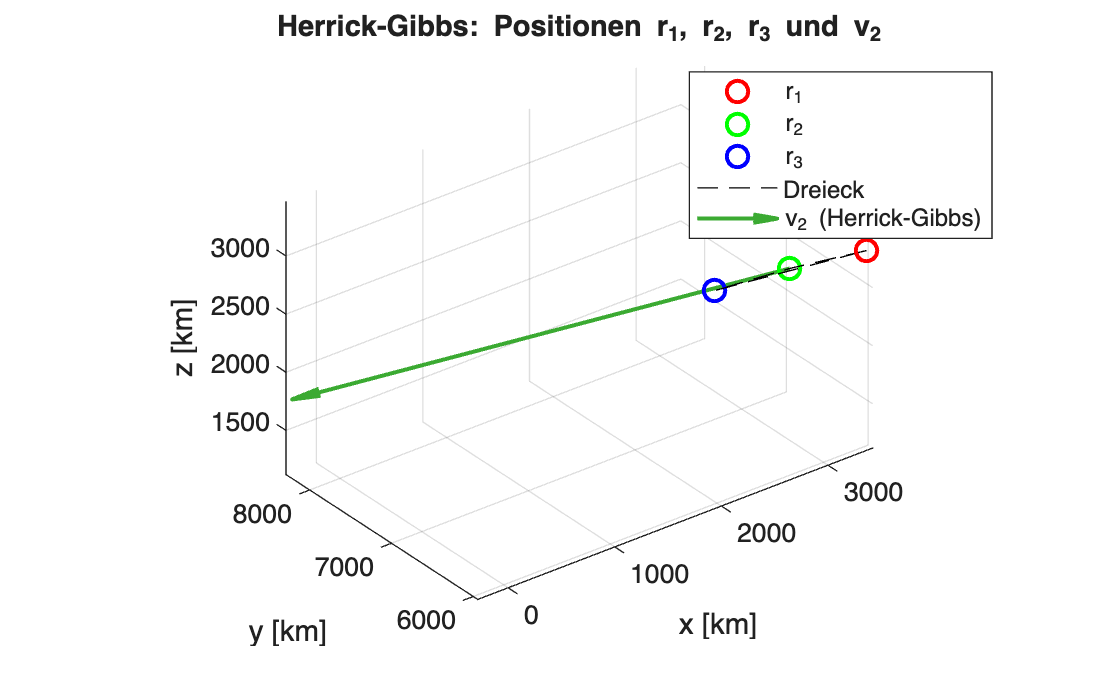

figure; hold on; grid on; axis equal;
title('Herrick-Gibbs: Positionen r_1, r_2, r_3 und v_2');
xlabel('x [km]'); ylabel('y [km]'); zlabel('z [km]');

% Punkte
plot3(r1(1), r1(2), r1(3), 'ro', 'MarkerSize', 8, 'LineWidth', 1.5);
plot3(r2(1), r2(2), r2(3), 'go', 'MarkerSize', 8, 'LineWidth', 1.5);
plot3(r3(1), r3(2), r3(3), 'bo', 'MarkerSize', 8, 'LineWidth', 1.5);

% Dreieck
plot3([r1(1) r2(1) r3(1) r1(1)], ...
      [r1(2) r2(2) r3(2) r1(2)], ...
      [r1(3) r2(3) r3(3) r1(3)], 'k--');

% v2-Pfeil an r2
scale_v = 500;   % nur für Darstellung
quiver3(r2(1), r2(2), r2(3), v2_HG(1), v2_HG(2), v2_HG(3), scale_v, 'LineWidth', 1.5);

legend('r_1', 'r_2', 'r_3', 'Dreieck', 'v_2 (Herrick-Gibbs)');
view(3);